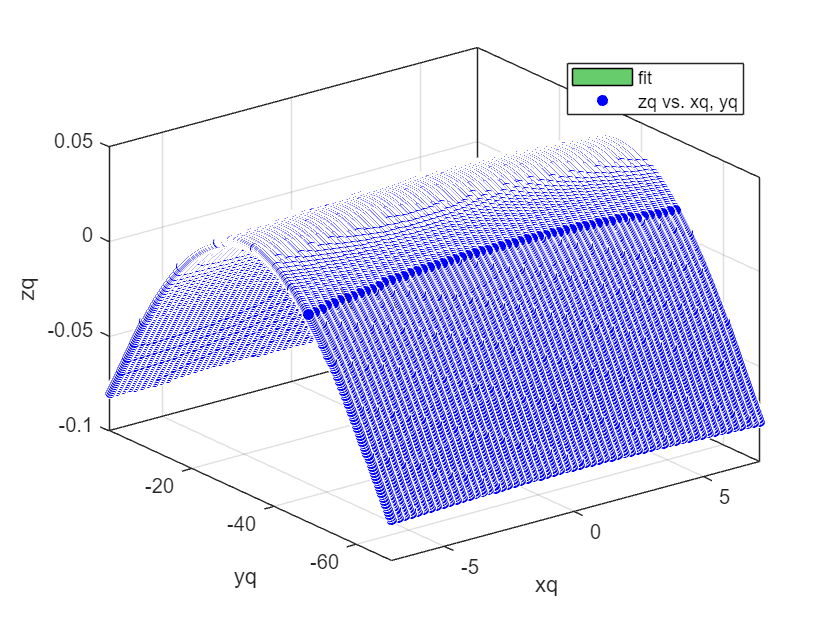

clc
clear
load("D:\temp\work\401\pointdata\251\251-1\AB_avg_f_061.mat");
xq = av.xi(:);
yq = av.yi(:); 
zq = av.z(:);
n = 5;%拟合方程次数
[f  gof] = createFit(xq, yq, -zq, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

-0.080853 + -0.0063197*Y + -6.599e-05*Y*Y + 3.6377e-07*Y*Y*Y + -7.9256e-09*Y*Y*Y*Y + -1.1523e-10*Y*Y*Y*Y*Y + 1.7438e-07*X*Y + 2.827e-07*X*Y*Y + 4.8689e-09*X*Y*Y*Y + 1.3151e-11*X*Y*Y*Y*Y + 1.3265e-06*X*X*Y + -4.8433e-08*X*X*Y*Y + -9.9375e-10*X*X*Y*Y*Y + -1.1198e-08*X*X*X*Y + -2.1235e-10*X*X*X*Y*Y + -1.7232e-09*X*X*X*X*Y + -2.3249e-09*X*X*X*X*X 


disp(gof)

           sse: 0.0013
       rsquare: 0.9999
           dfe: 15964
    adjrsquare: 0.9999
          rmse: 2.8292e-04




% idx = yq >= min(yq)+10;
% X = xq(idx);
% Y = yq(idx);
% Z = zq(idx);
% n = 5;%拟合方程次数
% [f  gof] = createFit(X, Y, Z, n);
% P = coeffvalues(f);%多项式系数向量
% s = dispf(P,n,n);
% disp(s)
% disp(gof)

## 双面

% load("D:\temp\work\401\pointdata\738\738-2\A.mat");
% data1 = [av.xi(av.in),av.yi(av.in),av.z(av.in)];
% load("D:\temp\work\401\pointdata\738\738-2\B.mat");
% data2 = [av.xi(av.in),av.yi(av.in),av.z(av.in)];
% data2(:,2) = -data2(:,2) - abs(min(data2(:,2)));
% ImpData = [data1;data2];
% xq = ImpData(:,1);
% yq = ImpData(:,2);
% zq = ImpData(:,3);
% % d = 0.5;%网格大小
% % [xq, yq, zq] = PreprocessDate(ImpData,d);
% n = 5;%拟合方程次数
% [f  gof] = createFit(xq, yq, zq, n);
% P = coeffvalues(f);%多项式系数向量
% s = dispf(P,n,n);
% disp(s)
% disp(gof)

% a = dlmread("D:\temp\work\401\pointdata\251\251-2\A.txt");
% b = dlmread("D:\temp\work\401\pointdata\251\251-2\B.txt");
